# Preprocess EEG data for Classification

### Filtering in the Frequency Domain

Most raw data is either messy or noisy, which is why you usually pre-process your data before training a machine learning model. To start with, we can use the ["filter"](https://www.mathworks.com/help/matlab/ref/filter.html) function to perform a moving average window filter on the data. This helps to reduce any noisy artifacts that might appear as spikes in the signal data. For more information on filtering read our documentation page on [Filtering Data](https://www.mathworks.com/help/matlab/data_analysis/filtering-data.html). 

function [signalDataSplitted, labelsEachSecond] = preprocessEEGdata(signalData, responseData)

% create the window
windowSize = 10; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;

% perform the moving average window filtering on the signal data
for i = 1: length(signalData)
    signalData{i} = filter(b, a, signalData{i});
end

### Preprocess the Data: Dividing into Smaller Time Chunks

One thing to note is that performing machine learning on sequence data can be time consuming, and often times having too many data points per sample can actually lead to a [degradation ](https://www.mathworks.com/help/signal/ug/waveform-segmentation-using-deep-learning.html?searchHighlight=extractFSSTFeatures&s_tid=srchtitle#WaveformSegmentationUsingDeepLearningExample-4)in model performance. To improve both speed and accuracy, we split the data into chunks of 1 second each (given the sampling rate of our data, this amounts to about 10000 samples per chunk). This also makes much sense at a non-technical level, as people performing this experiment will not be opening and closing their eyes on a millisecond basis, thus classifying larger time chunks is preferrable. Moreover, as we're interested in classifying future data on the scale of seconds spent in each state, we need our data to be of roughly that scale for the model to be able to give us the predictions that we are looking for. The choice of one second intervals was an intuitive time window for this problem, however larger or smaller intervals could also have been used depending on the desired scope of the predictions.

We can transform the data by performing the following steps:

Step 1.) Cut off the end portion of each experiment's signal data so that it is divisible by the desired number of samples per chunk.

Step 2.) Use the reshape function to get the data into the proper format of having each row represent a different time chunk.

Step 3.) Combine the data from all the experiments together. 

For a better visualization of this process, see the following figures:

#### Step 1.) Truncating the Length of the Data

First, our data starts as a single array for each experiment (each pair of .wav and .txt files). After choosing our chunk size to be one second, we want to cut off any remaining data that cannot be used into a full second long chunk (for example, a 5.5 second sample can be made into five one-second samples, and we would remove the last 0.5 seconds)

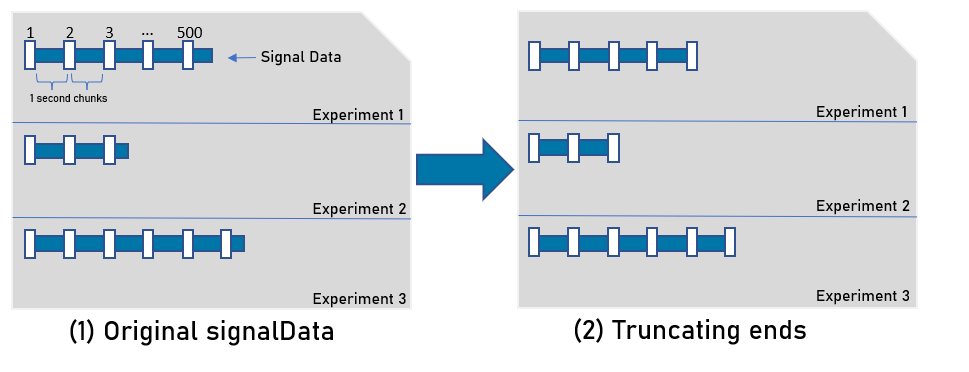

When we build our classifier, our MATLAB classification functions expect the data in the form of a matrix where each "row" represents a sample, in our case a 1 second chunk of time. Thus, we want to turn our single array containing all of the data for each experiment, into a matrix where each row is a one-second-long chunk. Thus, the first column of this matrix is the signal information for very first time sample in each second.

#### Step 2.) Reshaping the Data into Chunks

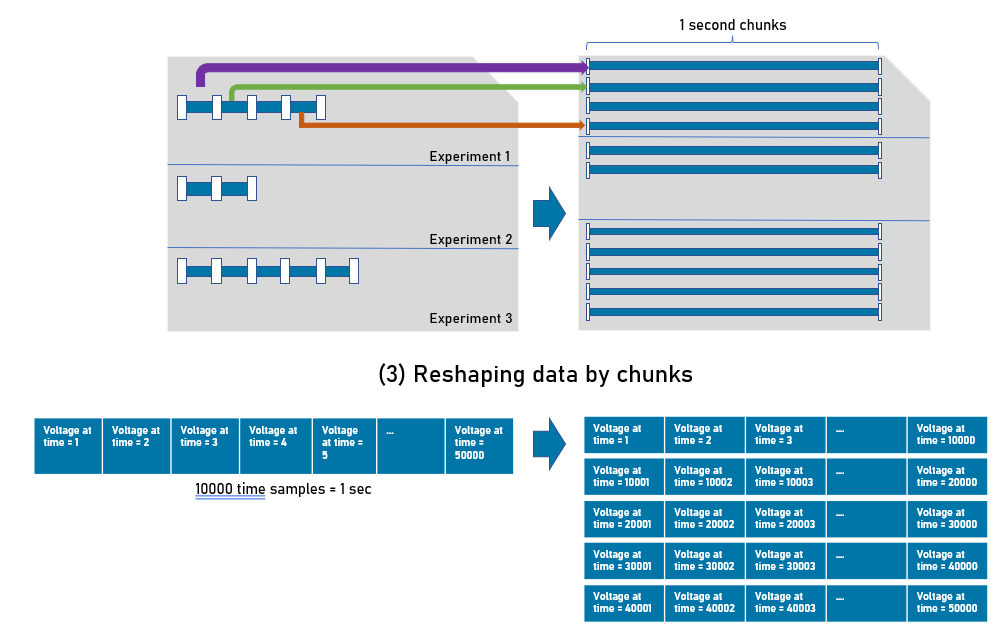

Finally, as we want to use the data from all of our experiments in the same classifier, we want to convert our many matrices (1 per experiment) into a single matrix containing all of our data. 

#### Step 3.) Combining Data from Different Experiments

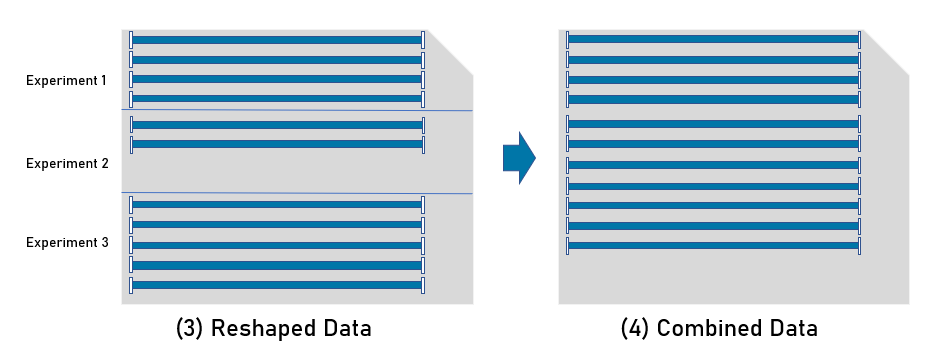

% split the data into smaller chunks
signalDataSplitted = {};
responseDataSplitted = {};
sizeOfChunks = 10000;

for i = 1: length(signalData)
    signalToSplit = signalData{i};
    responseToSplit = responseData{i};

    % Truncate data so that it is divisible by sizeOfChunks
    remainder = rem(width(signalToSplit), sizeOfChunks);
    signalToSplit = signalToSplit(1:end-remainder);
    responseToSplit = responseToSplit(1:end-remainder);
    
    % reshape data into proper size format
    signalToSplit = reshape(signalToSplit, sizeOfChunks, width(signalToSplit)/sizeOfChunks)';
    responseToSplit = reshape(responseToSplit, sizeOfChunks, width(responseToSplit)/sizeOfChunks)';
    
    % combine data from different experiments together
    signalDataSplitted = [signalDataSplitted ; mat2cell(signalToSplit, ones(size(signalToSplit,1), 1))]; %#ok<*AGROW>
    responseDataSplitted = [responseDataSplitted ; mat2cell(responseToSplit, ones(size(responseToSplit,1), 1))];
end

signalDataSplitted = signalDataSplitted(2:end); % getting rid of empty first index
responseDataSplitted = responseDataSplitted(2:end);

Note that now that we are dealing with 1 second time chunks of samples as our domain, we want to have our ground truth [response data] match this. In other words, instead of wanting labels for each sample point, now we want to label each of our time chunks. The simplest approach is to just take the mode through MATLAB's ["mode"](https://www.mathworks.com/help/matlab/ref/mode.html) function of the labels of all the sample points for each time chunk. This function outputs the most commonly appearing label within whatever was given to the function as input. We do this since we want to categorize the entire time chunk under one label, and the most commonly appearing label is the best way to go about that. We store these labels in "labelsEachSecond"

% create labels from response
labelsEachSecond = [];
for i = 1: length(signalDataSplitted)
    labelsEachSecond = [labelsEachSecond ; categorical(mode(responseDataSplitted{i}))]; 
end

### Preprocess the Data: Using FFT as our Domain Data

Recall our explanation of why analyzing data in the frequency domain is a powerful and useful tool for us from livescript ["EEG_anaylze.mlx" ](matlab:open('./EEG_analyze.mlx')). For this experiment, we gain much more power by using the frequency information of each time chunk, rather than the raw signal data itself. Recall the figure at the beginning of this script. This process falls under the "3rd" category in that diagram, where we need to derive features for our script. This is an essential part of the machine learning pipeline as the features are the information that the model relies on to learn and make predictions. The choice of one feature or another can have dramatic implications on the overall performance of the model. The following slice of code loops through each of the time chunks that we just created, and runs the ["fft" function](https://www.mathworks.com/help/matlab/ref/fft.html) on it to get the frequency information (which is one additional feature to the raw data). The remainder of the code turns the result of the fast-fourier transformation ("fft") into the single-sided amplitude spectrum.

% run fft on the chunks
for i = 1 : length(signalDataSplitted)
    L = length(signalDataSplitted{i});
    signalDataSplitted{i} = fft(signalDataSplitted{i});
    P2 = abs(signalDataSplitted{i}/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    signalDataSplitted{i} = P1;
end
signalDataSplitted = cell2mat(signalDataSplitted);

Note that while we chose to use the result of "fft" as our feature, there are other possible features that we could have used. Depending on the classification problem and the type of data available, there can be many possible features to choose from.

end